clear all;
close all;
clc;

## Problem 1

syms y x

### 1-1

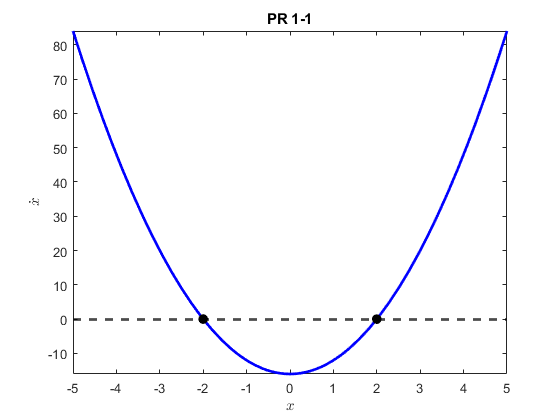

figure(1)
y = 4*x^2 - 16;

fplot(y, '-b', "LineWidth", 2)
hold on
yline(0, '--k', "LineWidth", 2)

xint = solve(y==0, "Real", true);
if ~isempty(xint)
    plot(xint, 0, '.k', 'MarkerSize', 25);
end

title("PR 1-1")
xlabel("$x$", "Interpreter", "latex")
ylabel("$\dot x$", "Interpreter", "latex")

hold off

### 1-2

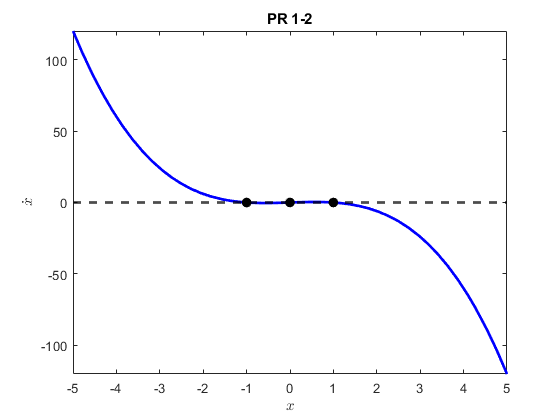

figure(2)
y = x - x^3;

fplot(y, '-b', "LineWidth", 2)
hold on
yline(0, '--k', "LineWidth", 2)

xint = solve(y==0, "Real", true);
if ~isempty(xint)
    plot(xint, 0, '.k', 'MarkerSize', 25);
end

title("PR 1-2")
xlabel("$x$", "Interpreter", "latex")
ylabel("$\dot x$", "Interpreter", "latex")

hold off;

### 1-3

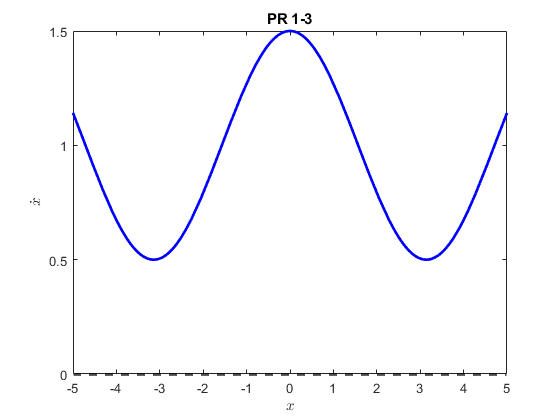

figure(3)
y = 1+1/2*cos(x);

fplot(y, '-b', "LineWidth", 2)
hold on;
yline(0, '--k', "LineWidth", 2);

xint = solve(y==0, "Real", true);
if ~isempty(xint)
    plot(xint, 0, '.k', 'MarkerSize', 25);
end

title("PR 1-3")
xlabel("$x$", "Interpreter", "latex")
ylabel("$\dot x$", "Interpreter", "latex")

hold off;

### 1-4

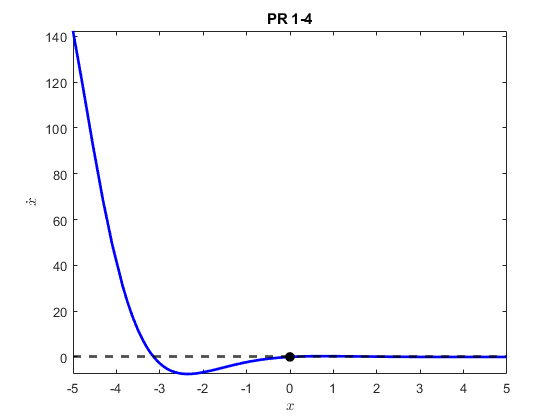

figure(4)
y = exp(-x)*sin(x);

fplot(y, '-b', "LineWidth", 2);
hold on;
yline(0, '--k', "LineWidth", 2);

xint = solve(y==0, "Real", true);
if ~isempty(xint)
    plot(xint, 0, '.k', 'MarkerSize', 25);
end

title("PR 1-4")
xlabel("$x$", "Interpreter", "latex")
ylabel("$\dot x$", "Interpreter", "latex")

hold off;

## Problem 2

## 2-1

figure(5);
y = 0

y = 0

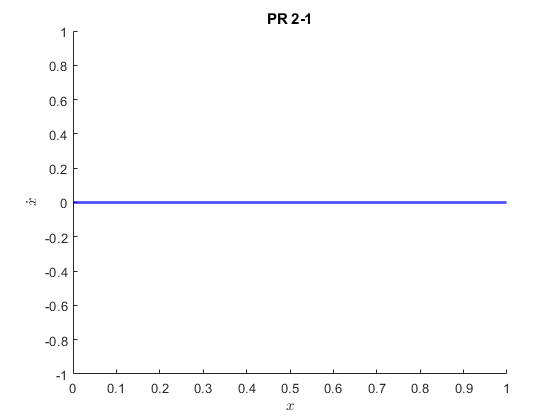

%fplot(y, '-b', "LineWidth", 2);
yline(0, '-b', "LineWidth", 2);

title("PR 2-1")
xlabel("$x$", "Interpreter","latex");
ylabel("$\dot x$", "Interpreter", "latex");

hold off;

## 2-2

figure(6)
y = sin(pi*x)

$$y = \sin\left(\pi \,x\right)$$

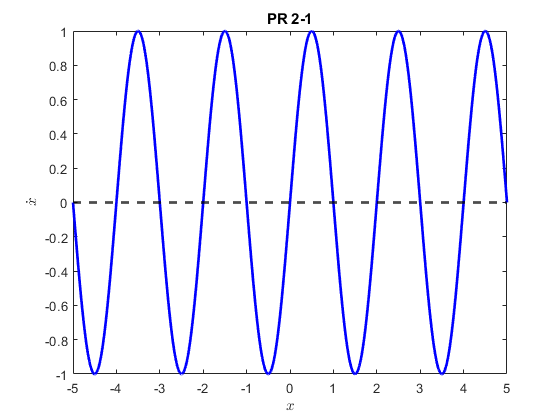


fplot(y, '-b', "LineWidth", 2);
hold on;
yline(0, '--k', "LineWidth", 2);

xint = solve(y==0, x, "Real", true);

title("PR 2-1")
xlabel("$x$", "Interpreter","latex");
ylabel("$\dot x$", "Interpreter", "latex");

hold off;

## 2-3

figure(7)
% Not possible in 1D


## 2-4

% ??

## Problem 3

syms x y z s r b

f1 = s*(y-x);
f2 = r*x - y - x*z;
f3 = x*y - b*z;
f = [f1;f2;f3];

jac = jacobian(f, [x,y,z]);
eq = solve(f==0, [x,y,z]);

% Compute linearization for each eq point

lin = cell(length(eq.x),1);
eigs = cell(length(eq.x),1);

disp("Jacobians")

Jacobians


for idx = 1:length(eq.x)
   lin{idx} = subs(jac, [x,y,z], [eq.x(idx),eq.y(idx),eq.z(idx)]); 
   eigs{idx} = eig(lin{idx});
   disp(vpa(lin{idx}))
end

$$\left(\begin{array}{ccc} -1.0\,s & s & 0\\ r & -1.0 & 0\\ 0 & 0 & -1.0\,b \end{array}\right)$$

$$\left(\begin{array}{ccc} -1.0\,s & s & 0\\ 1.0 & -1.0 & \sqrt{b\,\left(r-1.0\right)}\\ -1.0\,\sqrt{b\,\left(r-1.0\right)} & -1.0\,\sqrt{b\,\left(r-1.0\right)} & -1.0\,b \end{array}\right)$$

$$\left(\begin{array}{ccc} -1.0\,s & s & 0\\ 1.0 & -1.0 & -1.0\,\sqrt{b\,\left(r-1.0\right)}\\ \sqrt{b\,\left(r-1.0\right)} & \sqrt{b\,\left(r-1.0\right)} & -1.0\,b \end{array}\right)$$


disp("Case I")

Case I


for idx = 1:length(eq.x)
    disp(vpa(subs(eigs{idx}, [r,b,s], [0.5,1,1]),2))
end

$$\left(\begin{array}{c} -1.0\\ -1.7\\ -0.29 \end{array}\right)$$

$$\left(\begin{array}{c} 0.37\\ -1.4\\ -2.0 \end{array}\right)$$

$$\left(\begin{array}{c} 0.37\\ -1.4\\ -2.0 \end{array}\right)$$


disp("Case II")

Case II


for idx = 1:length(eq.x)
    disp(vpa(subs(eigs{idx}, [r,b,s], [2,3,5]), 2))
end

$$\left(\begin{array}{c} -3.0\\ -6.7\\ 0.74 \end{array}\right)$$

$$\left(\begin{array}{c} -1.3-1.7\,\mathrm{i}\\ -1.3+1.7\,\mathrm{i}\\ -6.5-2.3e-10\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} -1.3-1.7\,\mathrm{i}\\ -1.3+1.7\,\mathrm{i}\\ -6.5-2.3e-10\,\mathrm{i} \end{array}\right)$$

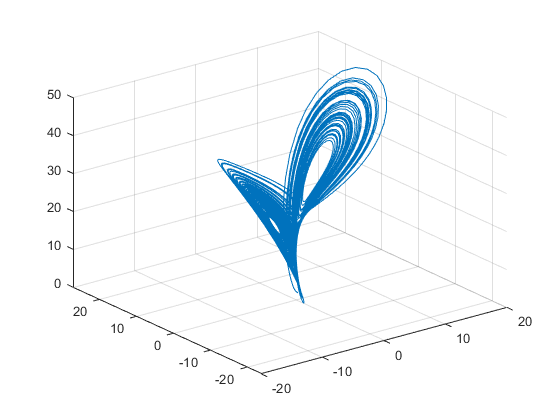



[t,X] = ode45(@(t,x)LorenzSystem(t,x,10,28,8/3), [0,100],[1;1;1]);
plot3(X(:,1), X(:,2), X(:,3));
grid

## Problem 4

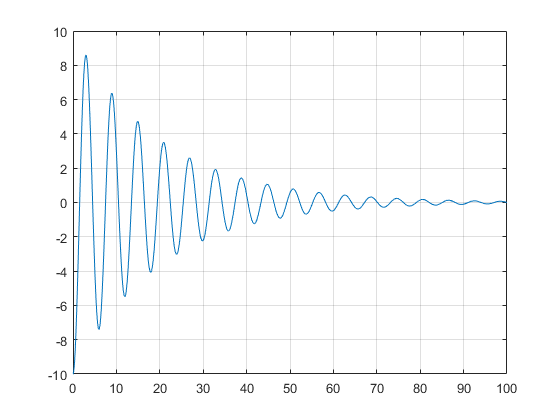

syms r L k m c x1 x2

f1 = x2;
f2 = -c/m*x2 - (k*r)/(m*(r+L))*x1;
f = [f1;f2];

r = -10;

[t,X] = ode45(@(t,x)PitchforBifurcation(t,x,0.1,1,1,r,1), [0,100], [-10;0]);
plot(t,X(:,1));
grid;

function XD=LorenzSystem(t,X,sigma,r,b)
    XD = [sigma*(X(2)-X(1));
          r*X(1)-X(2)-X(1)*X(3);
          X(1)*X(2)-b*X(3)];
end

function XD=PitchforBifurcation(t,X,c,m,k,r,L)
    XD = [X(2);
          -c/m*X(2) - (k*r)/(m*(r+L))*X(1)];
end